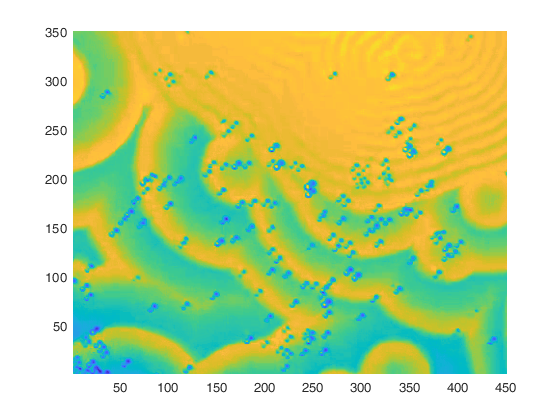

%%% view the data
[m,n,k]=size(BZ_tensor);% x vs y vs time data

for j=1:k
    A = BZ_tensor(:,:,j);
    pcolor(A),shading interp, pause(0.2)
end

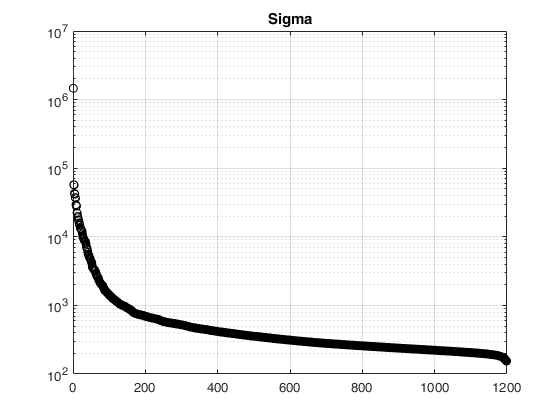

%%%% DMD
X = zeros(m*n,k);
for j=1:k
    X(:,j) = reshape(BZ_tensor(:,:,j),m*n,1);
   
end
X1 = X(:,1:end-1);
X2 = X(:,2:end);

slices = 1200;
t = linspace(0,1199,slices);
r = 200;

[Phi,omega,lambda,b,Xdmd,S] = DMD2(X1,X2,r,t);

fq1 = figure;
semilogy(abs(diag(S)),'ko');
title('Sigma')
grid on

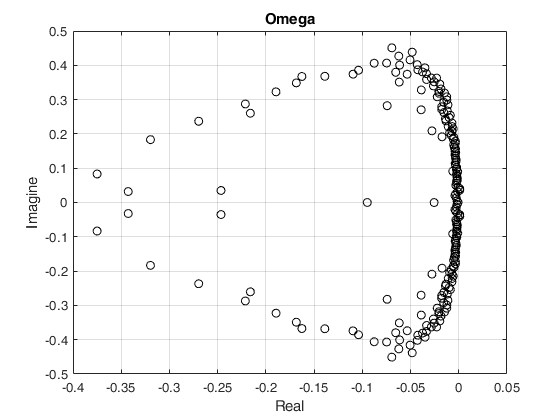


fq2 = figure;
plot(omega,'ko')
title('Omega')
xlabel('Real')
ylabel('Imagine')
grid on

%%% Time-delay DMD
X1_q2 =[];
X2_q2 =[];
r_q2 = 200;
kk = 5;
for j=1:kk
    X1_q2 = [X1_q2;X(:,j:(k-1)-kk+j)];
    X2_q2 = [X2_q2;X(:,j+1:(k-1)-kk+j+1)];
    
end
[Phi_q2,omega_q2,lambda_q2,b_q2,Xdmd_q2,S_q2] = DMD2(X1_q2,X2_q2,r_q2,t);
fq3 = figure;
semilogy(abs(diag(S_q2)),'ko');
title('Sigma')
grid on

fq4 = figure;
plot(omega_q2,'ko')
title('Omega')
xlabel('Real')
ylabel('Imagine')
grid on